# 行列の階数と変換

ワークスペース変数を消去，コマンドウィンドウを初期化，すべてのFigureウィンドウを閉じる．

clear;clc;close all;

rankVal=2;
switch rankVal

v =      1    -1     0
     1     2     3
     0     1     1


階数が3から1それぞれの場合

    case 3

ans = 2

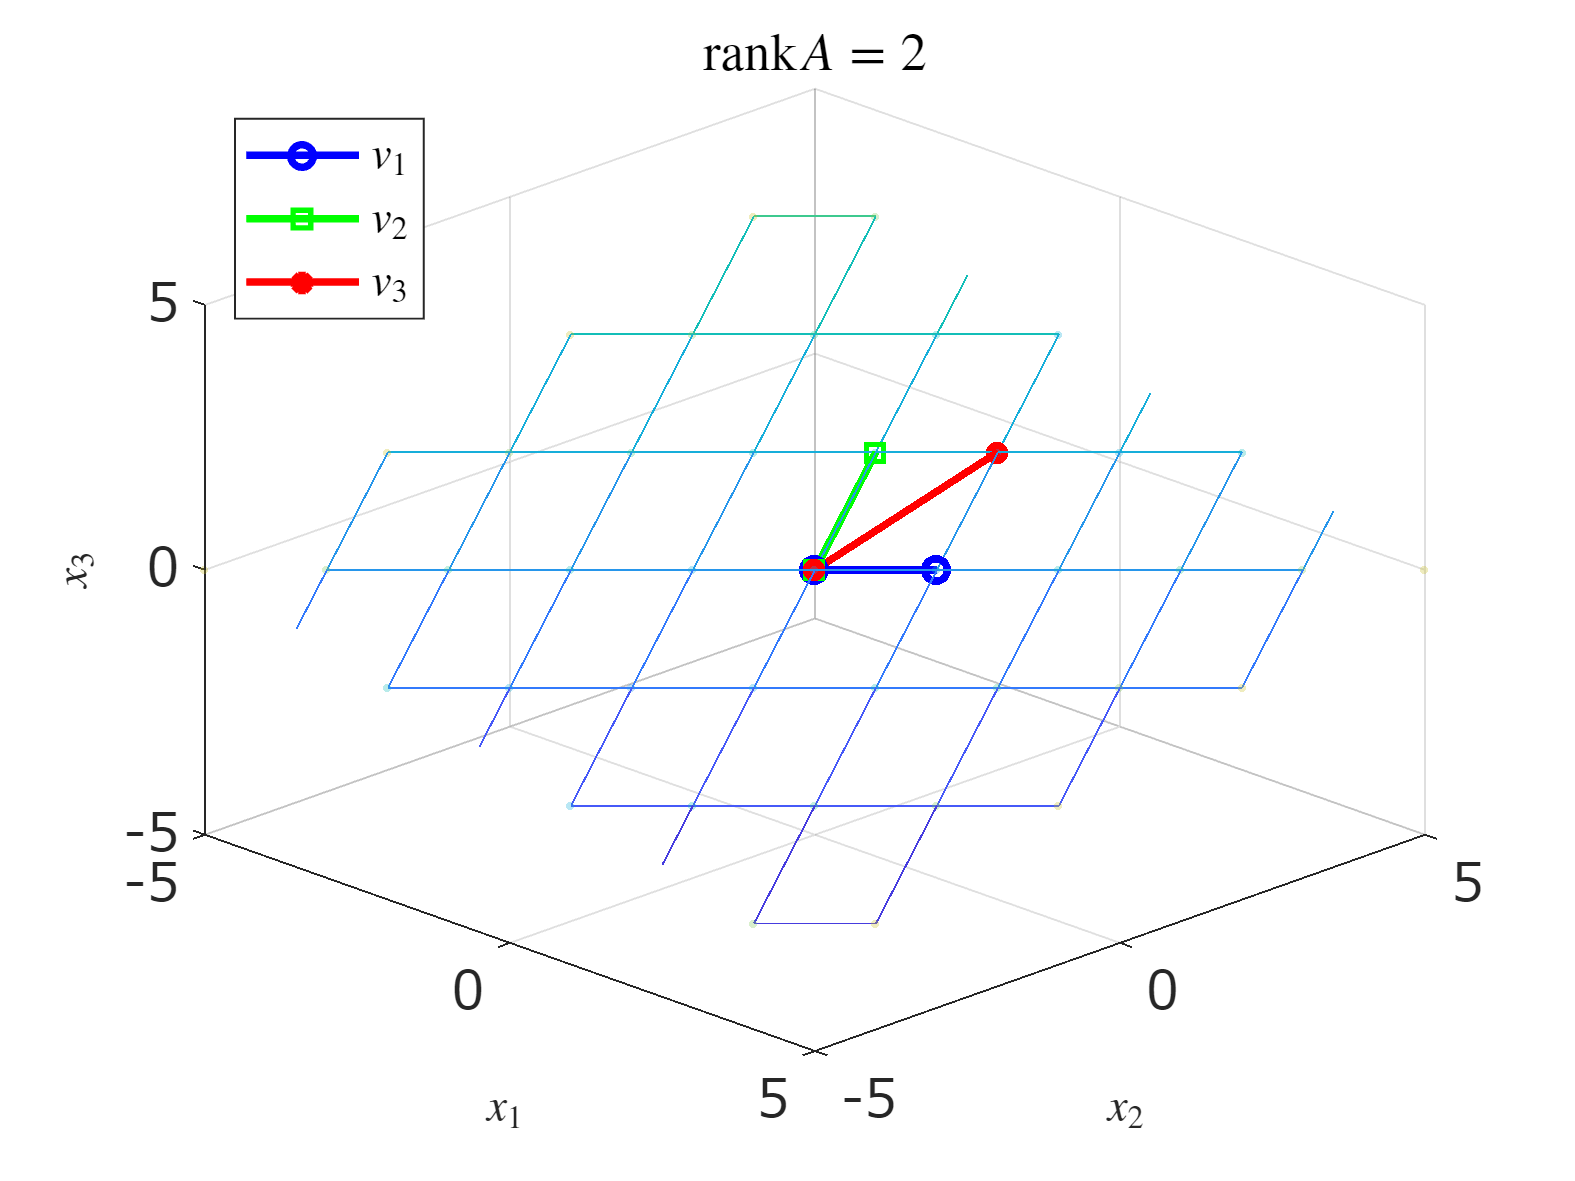

        v=[[1;1;0] [-1;2;1] [0;-1;2]]
    case 2
        v=[[1;1;0] [-1;2;1] [0;3;1]]
    case 1
        v=[[1;-2;-1] [-1;2;1] [0.5;-1;-0.5]]

end
rank(v)
plotData=[];
for n1=-4:4
    for n2=-4:4
        for n3=-4:4
            tmpV=v*[n1;n2;n3];
            plotData=[plotData;tmpV'];
        end
    end
end

X=zeros(9,9);
Y=zeros(9,9);
Z=zeros(9,9);
for n1=-4:4
    for n2=-4:4
        for n3=0
            tmpV=v*[n1;n2;n3];
            X(n1+5,n2+5)=tmpV(1);
            Y(n1+5,n2+5)=tmpV(2);
            Z(n1+5,n2+5)=tmpV(3);
        end
    end
end

figure;hold on;
grid on;
set(gca,'fontname','メイリオ','fontsize',14);
hv(1)=plot3([0 v(1,1)],[0 v(2,1)],[0 v(3,1)],'bo-','LineWidth',2);
hv(2)=plot3([0 v(1,2)],[0 v(2,2)],[0 v(3,2)],'gs-','LineWidth',2);
hv(3)=plot3([0 v(1,3)],[0 v(2,3)],[0 v(3,3)],'r*-','LineWidth',2);
if rankVal~=3
    mesh(X,Y,Z,'FaceAlpha',0);
end
scatter3(plotData(:,1),plotData(:,2),plotData(:,3), ...
    ones(size(plotData,1),1)*5, abs(plotData(:,1)),'o','filled',...
    'MarkerEdgeColor','none','MarkerFaceAlpha',0.3);
colormap(gca,"parula");
view([45,30]);
xlabel('$x_1$','Interpreter','latex','FontSize',12);

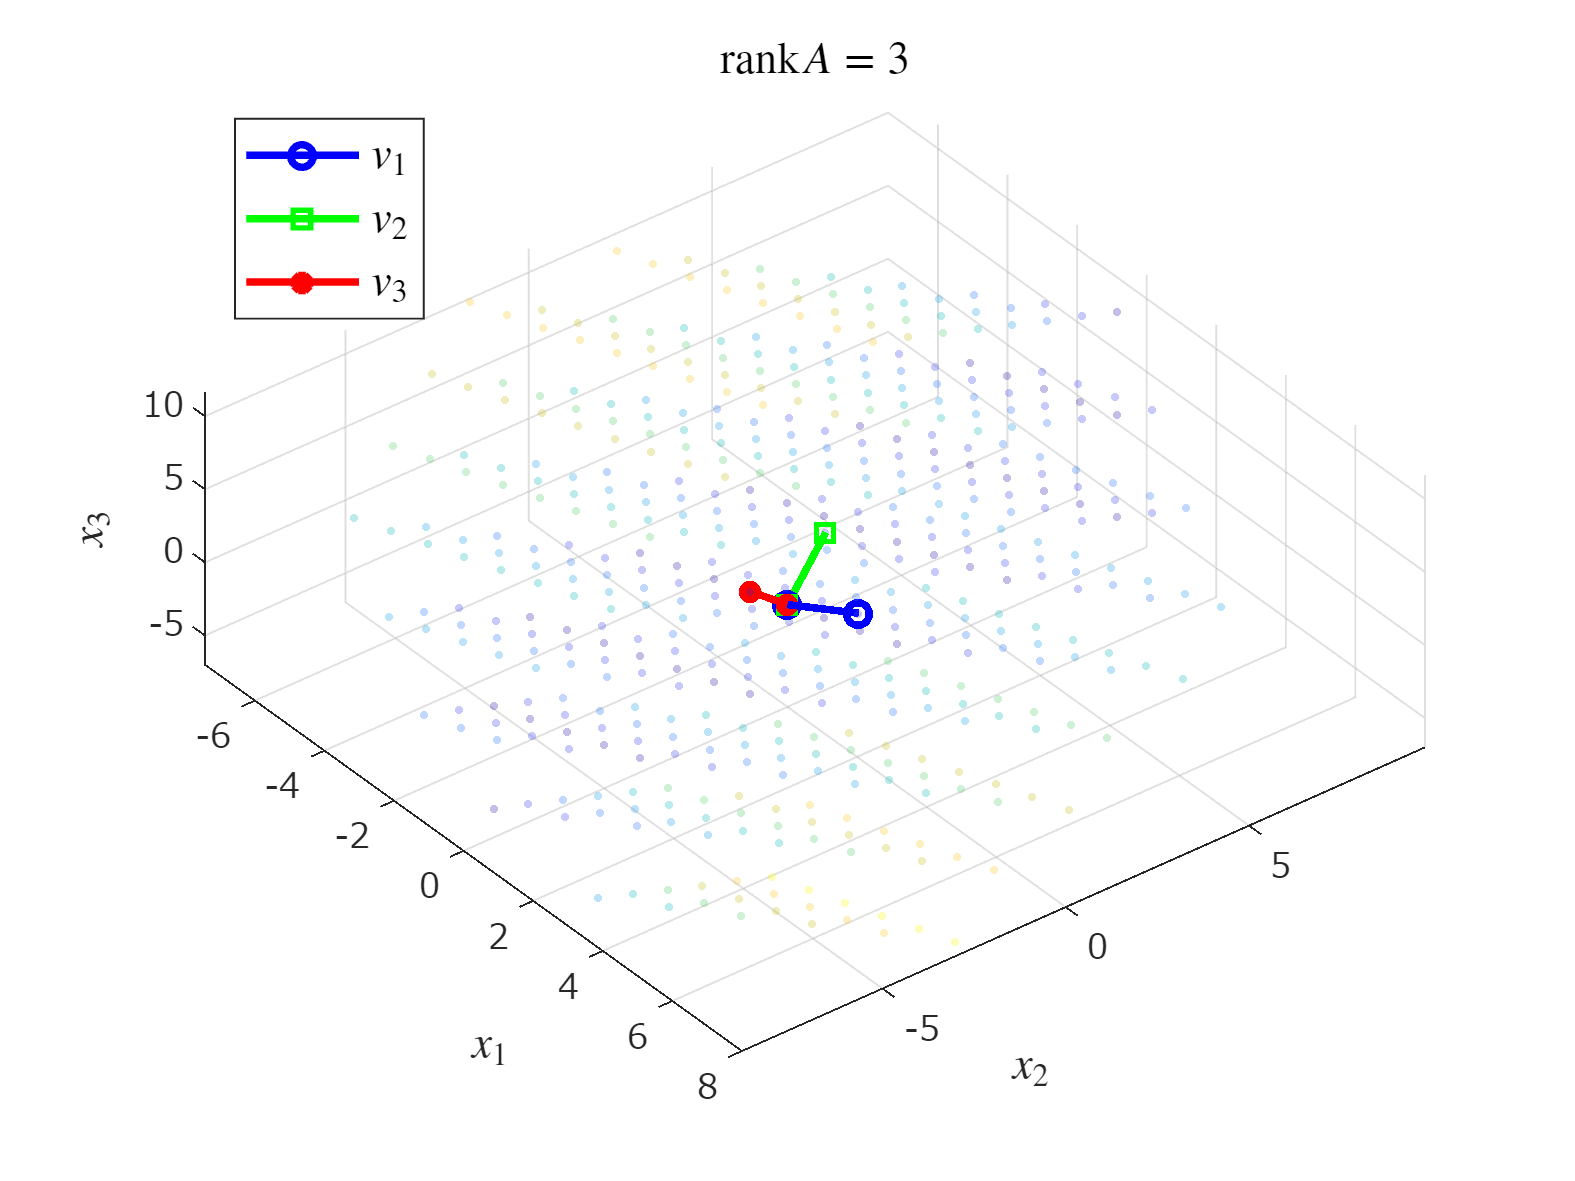

ylabel('$x_2$','Interpreter','latex','FontSize',12);
zlabel('$x_3$','Interpreter','latex','FontSize',12);
xlim([-5 5]);ylim([-5 5]);zlim([-5 5]);
legend(hv,{'$v_1$','$v_2$','$v_3$'},'Interpreter','latex','Location','northwest', ...
    'FontSize',12)
title(['${\rm rank} A=' num2str(rankVal) '$'],'Interpreter','latex',...
    'FontSize',14)

exportgraphics(gcf,['fig_linearDependancySample02-rank' num2str(rankVal) '.pdf']);


以下のコメントを外すと図が回転します．

% for n1=1:120
%     view([3*n1+45,30]);
%     pause(0.01)
% end
